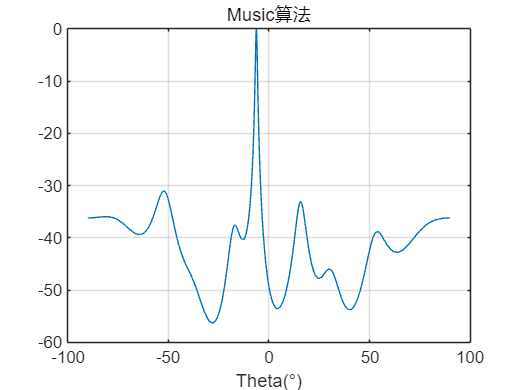

%https://blog.csdn.net/qq_36583373/article/details/109333087?ops_request_misc=&request_id=&biz_id=102&utm_term=music%E7%AE%97%E6%B3%95%E5%8E%9F%E7%90%86&utm_medium=distribute.pc_search_result.none-task-blog-2~all~sobaiduweb~default-0-109333087.nonecase&spm=1018.2226.3001.4187
clc; clear all; close all;
ArrayNum = 10;               %阵面阵元的列数
c = 3e8;             %光速                                     
doa_phi = [10, 30]; 
K = length(doa_phi); 

f0 = 2e9;           %载频
lambda = c/f0;       %波长
d = lambda/2;        %阵元间距
fs = 10e6;            %快时间采样速率（系统带宽）
Ts = 1 / fs;
Du = 0.001;          %脉冲占空比
Tp = 2e-6;  % 脉宽
B = 5e6;
gamma = B / Tp;
N = 100;          % 快拍数
t = 0:Ts:(N-1)*Ts;
%% 回波信号为LFM信号
s = rect(t-Tp/2, Tp).*exp(1i*gamma*pi.*t.^2).*exp(1i*2*pi*f0.*t); % LFM信号
% figure(1);
% plot(t, s);
% xlabel('t');
% ylabel('幅度');
% xlim([0, 5e-6]);

%% 生成导向矢量矩阵
phase = d/lambda*sind(doa_phi);
A = zeros(ArrayNum, K);
for i = 1:ArrayNum-1
    A(i+1,:) = A(i,:) + 1;
end
A = A .* phase;
A = exp(-1i*2*pi*A);

%% 生成接受到的数据矩阵X
SNR = 0;
S = ones(K, N);
S = 10^(SNR/20)*S .* s;
Noise=randn(ArrayNum, N).*exp(1i*2*pi*rand(ArrayNum,N));
X = A * S +  Noise;

%% 计算相关系数
Rxx = X*X'/N;
[U,V] = eig(Rxx);
V = diag(V);
[V,idx] = sort(V,'descend');
U = U(:,idx);
P = sum(V);
P_cum = cumsum(V);

J = find(P_cum/P>=0.9);
J = J(1);
Un = U(:,J+1:end);

theta = -90:0.1:90;

for i = 1:ArrayNum
    a_omega(i,:) = exp(-1i*2*pi*d.*sind(theta)/lambda*(i-1));
end

music = abs(diag(1./(a_omega'*(Un*Un')*a_omega)));
music = 10*log(music/max(music));
figure;
plot(theta, music);
title('Music算法');
xlabel('Theta(°)');
grid on;


function y = rect(t, Tp)
    y = double((t >= -Tp/2) & (t < Tp/2));
end